clear
addpath("geojsonR01\")

txt = readlines("N02-19_RailroadSection.geojson");
% txt = txt(4:end-3);
txt = strrep(txt,'鉄道区分','railsegments');
txt = strrep(txt,'事業者種別','companysegments');
txt = strrep(txt,'路線名','railname');
txt = strrep(txt,'運営会社','company');
geojson = jsondecode(strjoin(txt))

geojson = フィールドをもつ struct :
        type: 'FeatureCollection'
    features: [22016×1 struct]


railname = "山陽新幹線"

railname = "山陽新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#0072BA")

railname = "東海道新幹線"

railname = "東海道新幹線"

railcoordinate = parseCoordinate(geojson,railname);
hold on
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#FF7E1C")

railname = "東北新幹線"

railname = "東北新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#378640")

railname = "北海道新幹線"

railname = "北海道新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#03C13D")

railname = "九州新幹線"

railname = "九州新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#F62E36")

railname = "九州新幹線"

railname = "九州新幹線"

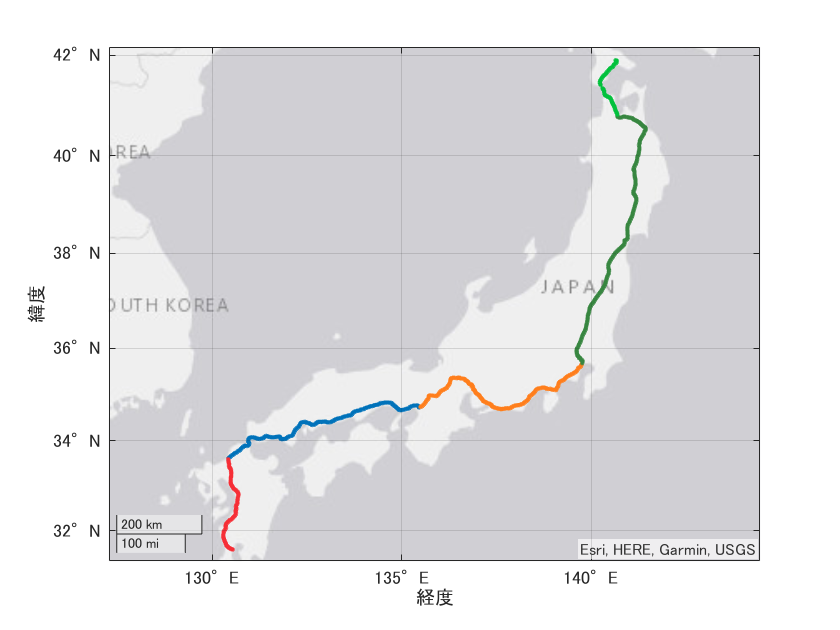

railcoordinate = parseCoordinate(geojson,railname);
geoplot(railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#F62E36")

hold off

function [railcoordinate] = parseCoordinate(geojson,railname)
    railcoordinate = [];
        for ii=1:length(geojson.features)
        if string(geojson.features(ii).properties.railname)==railname
            railcoordinate = [railcoordinate;geojson.features(ii).geometry.coordinates];
        end
        end
        railcoordinate = sortrows(railcoordinate);
end